# **Quantum Monte Carlo (QMC) Simulation**

This example shows how to use Quantum Monte Carlo (QMC) simulation in MATLAB® to compute the mean of a function of a random variable. There are a broad range of tasks in finance and economics that depend on Monte Carlo simulation, from option pricing to macroeconomic stress testing. While this example does not explore computational efficiency, research shows that QMC offers a quadratic speed-up compared to classic Monte Carlo methods.

This example follows [1] in considering an application of QMC to compute the mean of a function of a random variable. Specifically, the mean of a trigonometric function of an underlying normal distribution is computed. This calculation generalizes to many practical applications. For example, if the probability distribution represents the price of an underlying asset, the function could be the price of an option on that asset.

## **Problem Formulation**

Assume there is a random variable *x* that is normally distributed, and the function to be evaluated is


$$f\left(x\right)=\sin^2 \left(x\right)$$


The expected value of $f\left(x\right)$ is given analytically by $\mu =\frac{\sinh \left(1\right)}{e}$.

Calculate the value of $\mu$.

AnalyticMean = sinh(1)/exp(1)

## **Classic Monte Carlo**

For comparison, compute the mean $\mu$ with classic Monte Carlo. The steps to do this are:

- Generate a sample of points from the underlying distribution of *x.*

- Compute the function value at each point in the sample.

- Compute the sample mean of the function values.

func = @(x) sin(x).^2;
numSamples = 1000;
sampleData = randn(numSamples,1);
funcValues = func(sampleData);
MCMean = mean(funcValues)

Plot the sample, function values, and calculated mean.

tiledlayout(1,2)
nexttile
h1 = histogram(sampleData);
title("Sample Points")
nexttile
h2 = histogram(funcValues);
hold on
xline(MCMean,'--','MCMean');
hold off
title("Classic Monte Carlo","Mean of Function Values")

## **QMC Methodology**

First, define some parameters for the quantum simulation. Define the number of qubits for the probability distribution register as 5, and the number of qubits for the estimation register as 6. Then, discretize the probability distribution and function over a grid and compute the discrete mean of the function.

m = 5;  % Number of probability qubits
n = 6;  % Number of estimation qubits
M = 2^m;
N = 2^n;
probQubits = 1:m; 

x_max = pi;
x = linspace(-x_max,x_max,M)';
p = normpdf(x);
p = p./sum(p);

DiscreteMean = sum(func(x).*p)

The QMC methodology covered in [1] consists of the steps

- Load the probability distribution onto a quantum register of `m` qubits.

- Encode the value of the random variable onto a value qubit.

- Use amplitude estimation, with a register of `n` qubits, to estimate the probability of the value qubit being in the state ${\left∣1\right\rangle}$.

While there are other approaches for amplitude estimation (such as iterative amplitude estimation), this example uses quantum phase estimation.

The circuit diagram below summarizes the approach. The F block loads the probability distribution and encodes the random variable onto a value qubit. The Q blocks and the inverse Quantum Fourier Transform (QFT) are used for quantum phase estimation.

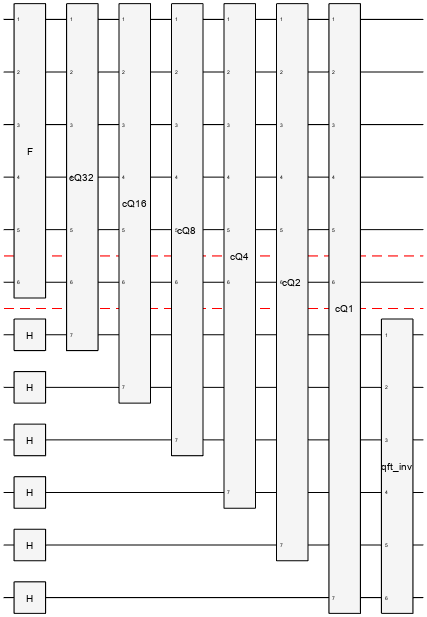

### **1. Load Probability Distribution**

Load the probability distribution onto m qubits. While [1] uses a quantum variational circuit to approximate the probability distribution, this example loads the probabilities directly onto the circuit. Use the `initGate` function to initialize the circuit.

A = initGate(probQubits,sqrt(p));
A.Name = 'Ainit';

Simulate the register to verify that the probability distribution loaded correctly.

circ = quantumCircuit(A);
state = simulate(circ);
figure
histogram(state,probQubits)
title("Simulated Probabilities")

### **2. Encode Random Variable**

Encode the discretized random variable function onto a value qubit.

valueQubit = m + 1;                        % Value qubit index
estQubits = (valueQubit + 1):(n + m + 1);  % Estimation qubits index

anglesR = 2*asin(sqrt(func(x)));

R = inv(ucryGate(probQubits,valueQubit,anglesR));
R.Name = "R";

Compute the probability of the value qubit being in the state ${\left∣1\right\rangle}$. The purpose of the F circuit is to evaluate the expected value of the random variable function.

F = compositeGate([A; R],[probQubits valueQubit],Name="F");
sF = simulate(quantumCircuit(F));
probability(sF,valueQubit,"1")

### **3. Quantum Phase Estimation**

Estimate the value of the value qubit using quantum phase estimation.

The controlled-Q block in the circuit diagram is implemented with several composite gates as outlined in [1]. Create a composite gate to represent this circuit element and plot the circuit to see the gates it contains.

controlQubit = valueQubit+1; % Re-mapped to estQubits in the loop below

cV = czGate(controlQubit,valueQubit); % For simplicity, do not wrap in a named CompositeGate

cZgates = [xGate([probQubits valueQubit])
          hGate(probQubits(1))
          mcxGate([probQubits(2:end) valueQubit controlQubit],probQubits(1),[])
          hGate(probQubits(1))
          xGate([probQubits valueQubit])];

cZ = compositeGate(cZgates,1:controlQubit,Name="cZ");

% Put the gates together to form controlled Q:

cQ = compositeGate([cV; inv(F); cZ; F; cV; inv(F); cZ; F],...
                   [probQubits valueQubit controlQubit],Name='cQ');

QPE = [];
for ii=1:n
    % Repeat the cQ gate as needed and map to the current control qubit:
    cQrep = compositeGate(repmat(cQ,2^(n-ii),1),...
                          [probQubits valueQubit estQubits(ii)],...
                          Name="cQ"+2^(n-ii));

    QPE = [QPE; cQrep];
end

plot(cQ)

## **Simulate Final Circuit**

Assemble the final circuit using the various component circuits, and plot the result. Specify the `QubitBlocks` name-value argument to display the two registers and the single value qubit.

circ = quantumCircuit([F;
                       hGate(estQubits); 
                       QPE; 
                       inv(qftGate(estQubits))]);
plot(circ,"QubitBlocks",[m 1 n])

Simulate the circuit.

state = simulate(circ);

## **Compare Results**

In terms of the phase $\theta$, the analytical mean is given by


$$\mu =\frac{1-\cos \left(\pi \theta \right)}{2}$$


Solve for $\theta$ using the analytic value for $\mu$.

AnalyticPhase = acos(-2*AnalyticMean + 1)/pi

Compare the analytic phase with the quantum phase estimation.

[states,probabilities] = querystates(state,estQubits);
plot(bin2dec(states)/N,probabilities)
xlim([.35 .65])
xline(AnalyticPhase,'--',"AnalyticPhase")
xlabel("\theta")
ylabel("Probability")
title("Phase Estimation with QMC")

The estimated phase is the first maximum in amplitude. Use the estimated phase to compute the mean value of the function, and compare the quantum value against the analytic value, classic Monte Carlo value, and discrete value.

y_ind = find(abs(probabilities - max(probabilities)) < 1e3*eps,1);
phase_estimated = bin2dec(states(y_ind))/N;
QMCMean = (1 - cos(pi * phase_estimated)) / 2;

ResultTable = table(AnalyticMean,MCMean,DiscreteMean,QMCMean)

## References

[1] Priazhkina, S., V. Skavysh, D. Guala, & T. Bromley. "Quantum Monte Carlo for Economics: Stress Testing and Macroeconomic Deep Learning." Bank of Canada working paper (2022). [https://www.bankofcanada.ca/wp-content/uploads/2022/06/swp2022-29.pdf](https://www.bankofcanada.ca/wp-content/uploads/2022/06/swp2022-29.pdf)

[2] Brassard, G., P. Hoyer, M. Mosca, & A. Tapp. "Quantum Amplitude Amplification and Estimation." Contemporary Mathematics 305 (2002): 53-74. [https://arxiv.org/pdf/quant-ph/0005055](https://arxiv.org/pdf/quant-ph/0005055)

[3] Rebentrost, P., B. Gupt, & T. R. Bromley. "Quantum Computational Finance: Monte Carlo Pricing of Financial Derivatives." Physical Review A, 98(2), 022321 (2018). [https://arxiv.org/pdf/1805.00109](https://arxiv.org/pdf/1805.00109)

[4] Stamatopoulos, N., D. J. Egger, Y. Sun, C. Zoufal, R. Iten, N. Shen, & S. Woerner. "Option Pricing Using Quantum Computers." Quantum 4, 291 (2020). [https://arxiv.org/pdf/1905.02666](https://arxiv.org/pdf/1905.02666)

[5] Woerner, S., & D. J. Egger. "Quantum Risk Analysis." npj Quantum Information 5(1), 15 (2019). [https://arxiv.org/pdf/1806.06893](https://arxiv.org/pdf/1806.06893)

*Copyright 2023 The MathWorks, Inc.*